# **FIT3081 IMAGE PROCESSING**

## **ALGORITHM - CAR NUMBER PLATE DETECTION**

## **GROUP - 09**

### **MEMBERS : 1) Cheah Meng Yew (30221846)**

### **                      2) Yeow Kin Ren (30762243)**

### **                      3) Bryan Hooi Yu Ern (30221005)**

## PRE-PROCESSING

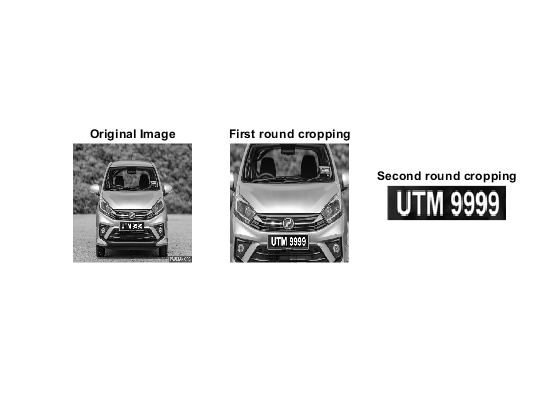

% Reading in an image and converting it to grayscale as well as
% resizing it to a predetermined size (512x512)
I = rgb2gray(imresize(imread("Plate1.jpg") , [512,512]));

% First round of cropping to about central 60% of the image
I_cropped_1 = imcrop(I, [103 103 307 307]);

% Extraction of specific image corner points into an object
corners = detectHarrisFeatures(I_cropped_1).selectStrongest(25);

% Detection and removal of outliers from the Location component
% in the corners matrix based on the median. Assumption is that
% these resulting points envelop the car's number plate characters
TF = rmoutliers(corners.Location,'median');

% Obtaining the minimum row and column values and determining the
% most appropriate width and height of the crop rectangle
X = min(TF(:,1));
Y = min(TF(:,2));
w = max(TF(:,1)) - X;
h = max(TF(:,2)) - Y;

% Second round of cropping using the values obtained above
I_cropped_2 = imcrop(I_cropped_1, [X-10  Y-5  w+20 h+10]);

% Display Output Images
figure,
subplot(1,3,1); imshow(I); title("Original Image");
subplot(1,3,2); imshow(I_cropped_1); title("First round cropping"); 
subplot(1,3,3); imshow(I_cropped_2); title("Second round cropping");

## OUTLINE EXTRACTION

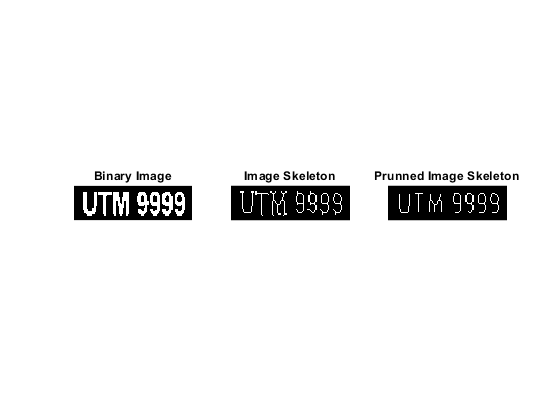

% Convert the cropped image into a binary image
I_after = imbinarize(I_cropped_2);

% Removal of boundary pixels from image until pixels that make
% up the image's skeleton remains
skel = bwmorph(I_after,'skel', Inf);

% Removal of spur pixels from the skeleton to produce a smoother
% skeleton. 3 rounds of spur removal applied
prunned = bwmorph(skel, "spur", 3);

% Display Output Images
figure,
subplot(1,3,1); imshow(I_after); title("Binary Image");
subplot(1,3,2); imshow(skel); title("Image Skeleton");
subplot(1,3,3); imshow(prunned); title("Prunned Image Skeleton");

## LETTER/NUMBER SEPARATION

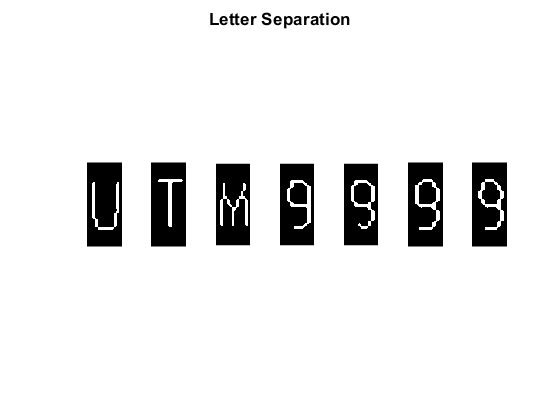

% If got two rows then split it in half and join it back with the first row
[w, h] = size(prunned); 
d = h-w;
if d <= 25
    % gets all the boundary 
    [character_head, character_width] = getLump(prunned, 1);
    Image = [];
    % loop through all the boundary and crop out
    % the segments of the boundary , resize it 
    % and store it in the Image array 
    for i = 1:length(character_head)
        [k, w] = size(prunned);  
        X = 0;
        Y = character_head(i);
        h = character_width(i);
        im = imcrop(prunned, [X Y w h]);
        im = imresize(im, [500 1200]);
        Image = [Image {im}]; 
        %subplot(1,length(character_head) ,i ), imshow(mat2gray(im));
    end
    % Merge all the found segments in a montage 
    % to form a one row car plate 
    a = montage(Image , 'Size', [1 2]);
    % clean the data 
    a = a.CData;
    a = imbinarize(a); 
    prunned = bwmorph(a, 'thicken'); 
end

% gets all the boundaries in the one row car plate 
[character_head,character_width] = getLump(prunned, 0); 

% loop through all the boundary and crop 
% out the segments and show it in a subplot 
figure, 
for i = 1:length(character_head)
    [h, z] = size(prunned);  
    X = character_head(i);
    Y = 0;
    w = character_width(i);
    im = imcrop(prunned, [X-2 Y w+2 h]);
    im = imresize(im, [1200 500]);
    subplot(1, length(character_head), i), imshow(mat2gray(im));
end
sgtitle("Letter Separation", "FontWeight", "bold");

dir == 1 means row by row 

dir == 0  means column by column 

function [character_head, character_width] = getLump(prunned, dir)
    sh = prunned;
    [m, n] = size(sh);
    % if dir is 1 , it means it is row by row , then choose the 
    % below setting for the algorithm 
    if dir  
        % pick a correct rectangle se 
        se2 = strel("rectangle" , [1, 600]); 
        % Both of this padarray are necessary 
        % so that if a segment is clearly shown 
        sh = padarray(sh, [5, 0], "pre"); 
        sh = padarray(sh, [5, 0], "post"); 
        % loop through the column 
        loop_row_column = m;
    % different setting if dir = 0 
    else 
        se2 = strel('rectangle', [600, 1]); 
        sh(1:m, 1:3) = 0; 
        loop_row_column = n;
    end
    
    % This is the core part , where i dilate the image 
    % to get the boundary 
    for k = 1:1
        %figure,imshow(sh);title("before dilate");
        sh =  imdilate(sh, se2);
    end 
    i = 1;
    head = 0;
    tail = 0;
    character_head = [];
    character_width = []; 
    % loop though the column and row depeding on dir = 0|1
    while i < loop_row_column
        % sets the correct current value and previous value 
        % in the current pixel and previous pixel value 
        % cur_val means the current pixel value 
        % prev_val means the previous pixel value 
        if dir  
            cur_val = sh(i, n);
            prev_val = sh(max([1,i-1]), n);
        else 
            cur_val = sh(m, i);
            prev_val = sh(m, max([1, i-1]));
        end
        % If no boundary have been found yet , head will be 0
        if head == 0  
            % if there is a change in pixel value , it means the head of
            % the boundary have been found 
            if cur_val ~= prev_val 
                head = i;
            else
                i = i + 1;
            end
        else
            % if the head of the boundary have been found , then 
            % check if the tail of the boundary have been found 
            if head ~= 0 && tail == 0 
                % If the current value is 1 , it is still in the 
                % boundary 
                if cur_val == 1 
                    i = i + 1;
                % if there is a change in pixel value again , then 
                % we have found the end of the boundary 
                % record it and reset the head and tail 
                else 
                    tail = i;
                    character_head = [character_head, head]; 
                    character_width = [character_width, tail-head];
                    i = i + 1; 
                    head = 0; 
                    tail = 0;
                end
            else
                i = i + 1; 
                head = 0; 
                tail = 0; 
            end
        end
    end
end